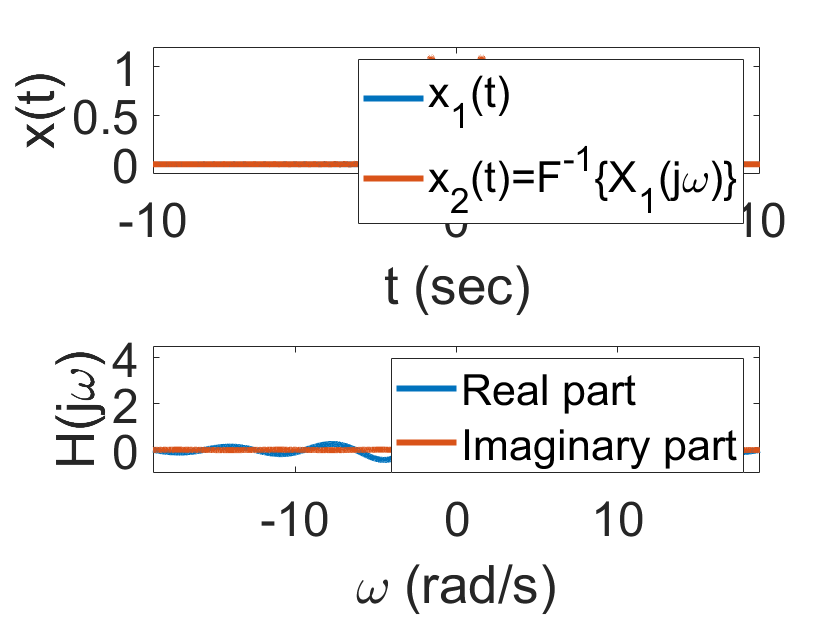

% Plotting the spectrum of a rectangular pulse
t=-10:.01:10;
w=-6*pi:.01:6*pi;
x1=rectpuls(t/2);
X=ctft(t,x1,w);
x2=ictft(w,X,t);
subplot(2,1,1)
plot(t,x1,'linewidth',3);
hold on
plot(t,real(x2),'linewidth',3);
set(gca,'fontsize',24)
axis([-10 10 -0.1 1.2])
legend('x_1(t)','x_2(t)=F^{-1}\{X_1(j\omega)\}')
xlabel('t (sec)')
ylabel('x(t)')
subplot(2,1,2)
plot(w,real(X),'linewidth',3);
hold on
plot(w,imag(X),'linewidth',3);
set(gca,'fontsize',24)
legend('Real part','Imaginary part')
axis([-6*pi 6*pi -1 4.5])
xlabel('\omega (rad/s)')
ylabel('H(j\omega)')